**Carlo Colizzi & Daniel Park | ModSim 2020 Final Project**

# **Ball Bouncing Simulation**

## **Question: **

### *Prediction: How will different materials and launch heights of a ball affect its position trajectory?*

This is a prediction question because we are trying to find how different parameters such as material of the ball and launch heights will affect a ball's bouncing trajectory. We chose this question because although it can be relatively simple to initially model, iterations can allow us to expand into various different topics. We first created a model using the kinematics equations of motion, and then iterated onto modelling it with ODEs, successively adding the two dimensions components together to obtain a projection onto the x-y space. This allowed us to analyse the trends created by the sweeping of some parameters, hence allowing us to gather our results.

## **Methodology/Model: **

### Diagrams

In order to accurately answer this question, we first designed two diagrams of our model.

***Schematic and Free-Body-Diagrams***

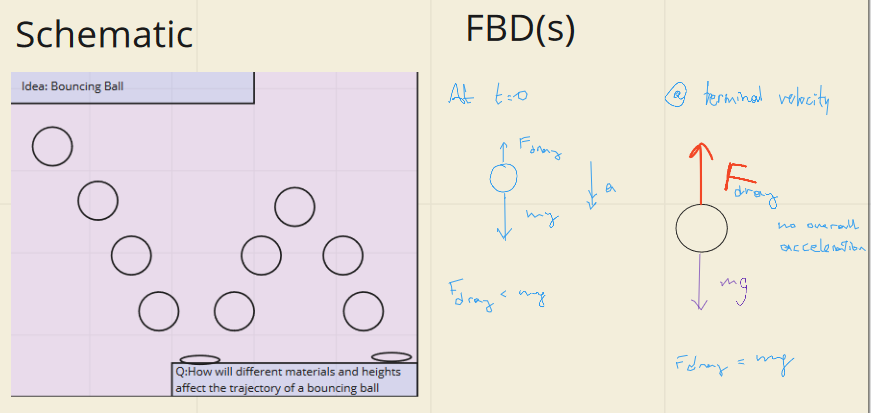

***Stock and Flow Diagram***

**Potential energy** (stock) is a form of energy that results from an object's position, which would be how high the ball is dropped originally. However, when the ball is dropped and free falls towards the floor as it loses **height** (flow), the potential energy is transformed into **kinetic energy **(stock). The decrease in potential energy is exactly equal to the increase in kinetic energy.The sum of an object's potential and kinetic energies is called the object's **mechanical energy**.

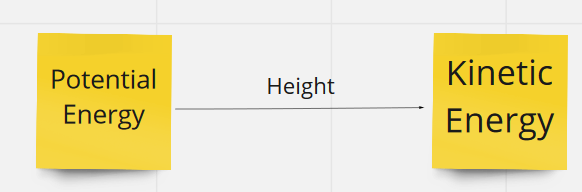

### Equations

The Kinematics Equations used to describe the motion of the ball without considering the forces that cause them to move (as shown in the first model)

- 
$$v=\textrm{at}+v_0$$


- 
$$s=\mathrm{ut}+\frac{1}{2}{\mathrm{at}}^2$$


- 
$$v^2 =u^2 +2\textrm{as}$$


- 
$$s=\frac{1}{2}\left(u+v\right)t$$


- 
$$s=\mathrm{vt}+\frac{1}{2}{\mathrm{at}}^2$$


In these equations, the associated variables represent

- u = initial velocity

- v = final velocity

- s = displacement

- a = acceleration

- t = time

### ODEs

Given the above diagrams, we were able to obtain the following ODEs for motion in the y-dimension:

$\frac{\mathrm{dy}}{\mathrm{dt}}=g$ which, in terms of position, translates to $\frac{d^2 x}{{\mathrm{dt}}^2 }=g$

We can divide this into two different first order ODEs, so it can be later accepted by ode45.


$$\frac{\mathrm{dv}}{\mathrm{dt}}=g$$



$$\frac{\mathrm{dv}}{\mathrm{dt}}=y$$


Regarding motion in the x-dimension, based on kinematic equations, the velocity of an object (ignoring air resistance) is constant throughout its entire motion. 

$s=\mathrm{ut}+\frac{1}{2}{\mathrm{at}}^2$ where a = 0, because there is no air resistance, therefore $s=\mathrm{ut}$

### Assumptions and Abstractions

In order to accurately model our system, we first had to take a certain number of assumptions.

- We do not take in account the sizes of the balls (we assume that all the balls are the same sizes)

- The ball's air resistance is negligible

- The ball is released from rest in the y-direction where it is not pushed down or up (the initial velocity in the y-direction is zero)

- No energy is lost due to the deformation of the ground (at an atomic level)

### Parameters

- Coefficient of Resitution (Based on the type of ball that will be simulated) 

- Launch Height 

### Development and Refinement

First, we decided to use the kinematic equations of motion to come up with a first iteration of the model. 

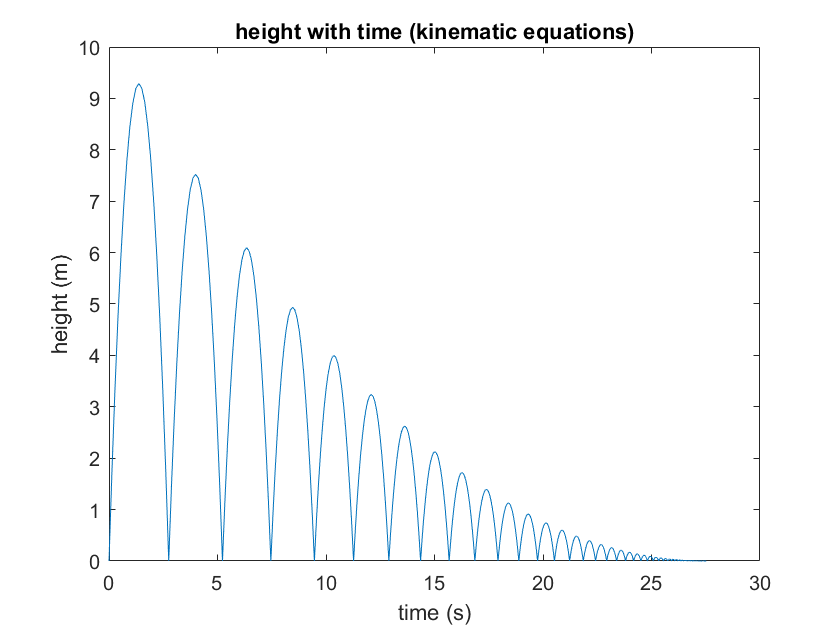

clf
ball_bounce
plot(x,y)
xlabel("time (s)")
ylabel("height (m)")
title("height with time (kinematic equations)")

This helped us visualize how the balls would act over time from the starting height 0 using the kinematic equations for the ball's trajectory in both the x and y directions. We used this graph as a reference to graph the ball bouncing using a system of ODEs later on and sweeping through the different ball type and height parameters.

### Verification

Before we started to transfer the graph into a second order ODE from a kinematics-based graph, we first created an ODE graph that represents the ball's trajectory in the y direction over time. We used this graph to make sure that the behavior of the ball bouncing in the y direction made sense. This will let us know that when we have the graph that will give us the ball trajectory of different materials and drop heights, we will get a graph based on reasonable foundations.

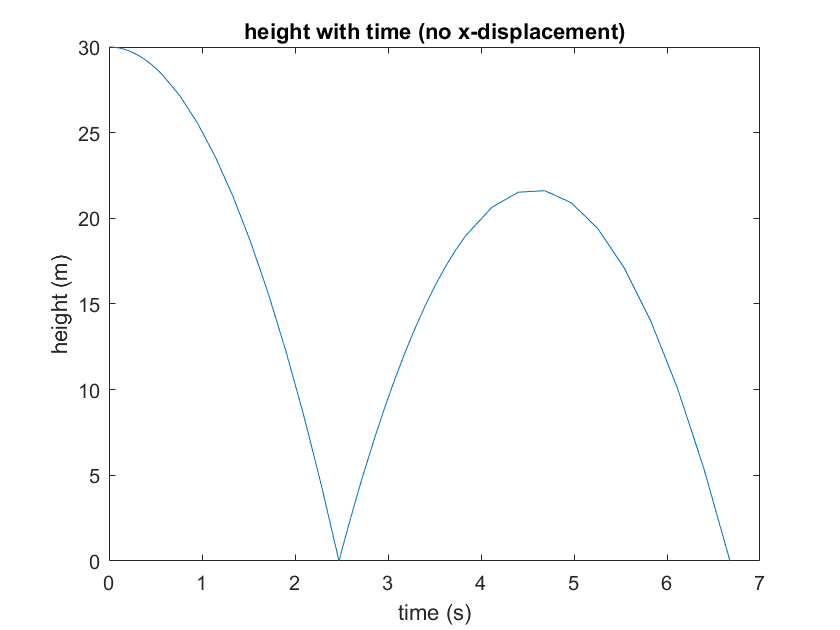

clf; figure;
[T, H] = bouncing_y(30);

plot(T, H(:,1), "-"); % position
xlabel("time (s)")
ylabel("height (m)")
title("height with time (no x-displacement)")

**Validation:**

If we were to validate our model, we would most likely get real data from a physical bouncing ball. We would collect different types of balls with different coefficient of restitutions and then get ball drop data from a tall building we can scale to get the most accurate data on our current parameters. We would do this real life simulation on our own, make sure both of our constraints and parameters are similar in our script and in the real life model, and compare them together.

## **Results:**

During this third iteration, we decided to put our code in a loop to simulate more bounces. We also added the equation for motion in the x-dimension, now plotting displacement in y agains displacement in x.

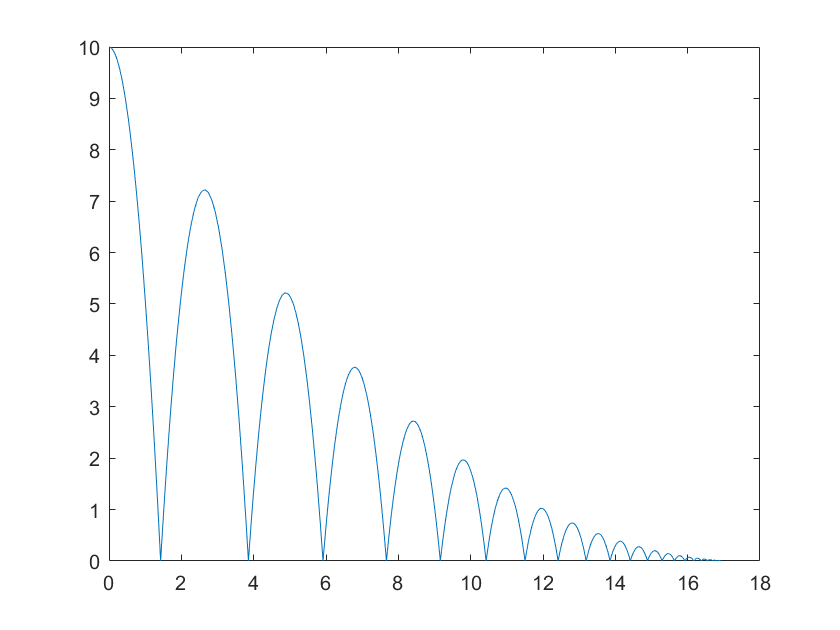

clf; figure;

[x, y] = bouncing_xy(10, 1, 0.85);
plot(x, y(:, 1))

### Sweeping Heights

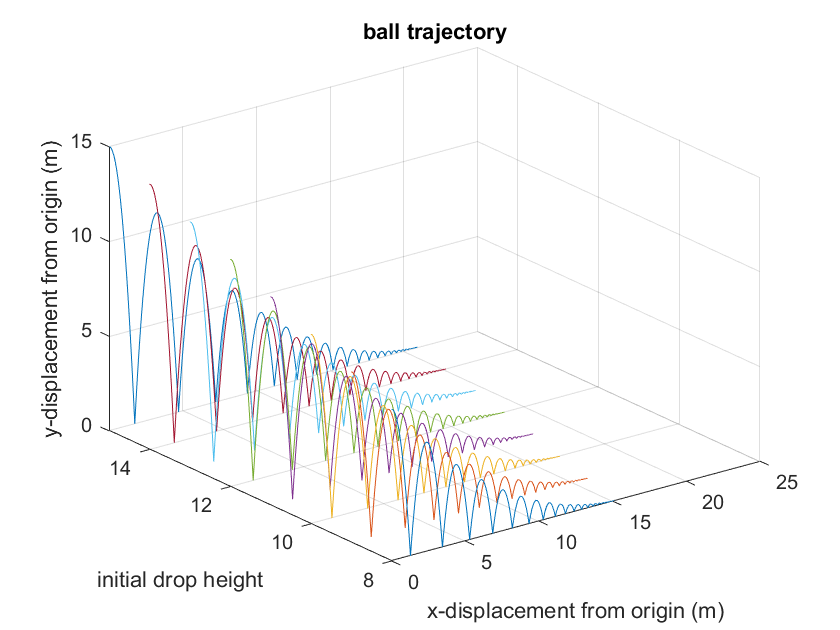

clf; figure
height = [8:1:15];
X = zeros(5000, length(height));
Y = zeros(5000, length(height));
Z = NaN(5000, length(height));

for i = 1:length(height)
[x, y] = bouncing_xy(height(i), 1, 0.85);

X(1:length(x), i) = x;
Y(1:length(y), i) = y(:, 1);
Z(1:length(x), i) = height(i).*ones(size(x(i)));

end

plot3(X, Z, Y); colormap("default"); grid;

ylim([height(1), height(end)])
xlabel("x-displacement from origin (m)")
zlabel("y-displacement from origin (m)")
ylabel("initial drop height")
title("ball trajectory")

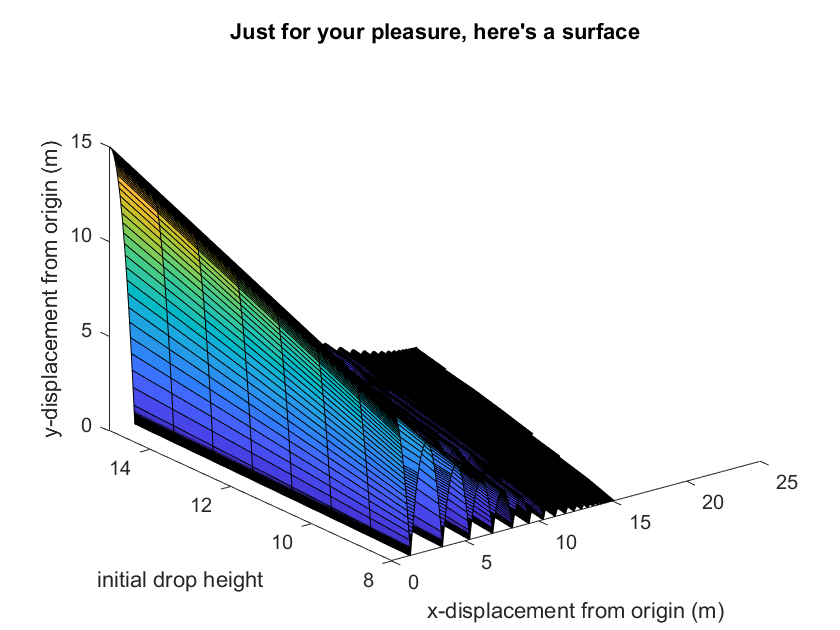


surf(X, Z, Y); colormap("default"); grid;

ylim([height(1), height(end)])
xlabel("x-displacement from origin (m)")
zlabel("y-displacement from origin (m)")
ylabel("initial drop height")
title("Just for your pleasure, here's a surface")

Please Note: the gaps that can be seen are due to an incompatibility with surf(), and not errors in calculations.

### Sweeping COR

We proceeded to sweep the other parameter we are investigating: the material of the ball. Different materials mostly affect the ball in just one way: they change how high it bounces. This is determined by the coefficient of restitution, which is 1 for perfectly elastic collisions and under this value for inelastic collisions, where energy is lost to surroundings. 

Below a table of some materials and their COR can be found. 

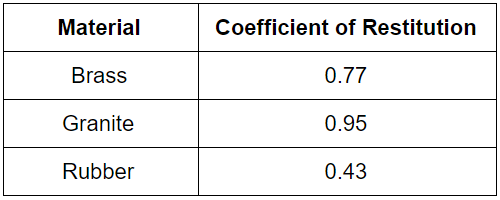

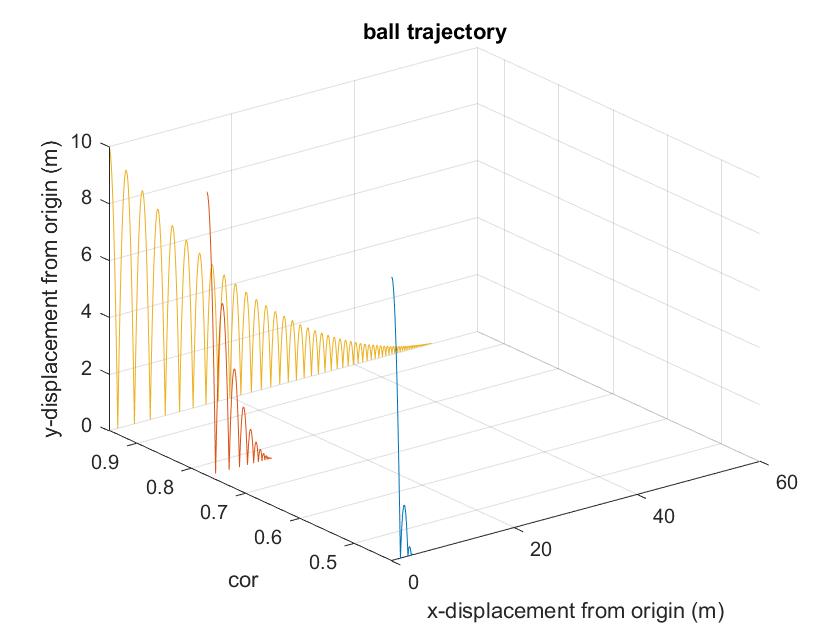

clear;
clf; figure
cor = [0.43, 0.77, 0.95]; %Brass, Granite and Rubber Respectively
X = zeros(5000, length(cor));
Y = zeros(5000, length(cor));
Z = NaN(5000, length(cor));

for i = 1:length(cor)
    [x, y] = bouncing_xy(10, 1, cor(i));
    
    X(1:length(x), i) = x;
    Y(1:length(y), i) = y(:, 1);
    Z(1:length(x), i) = cor(i).*ones(size(x(i)));
end
plot3(X, Z, Y); colormap("default"); grid;

ylim([cor(1), cor(end)])
xlabel("x-displacement from origin (m)")
zlabel("y-displacement from origin (m)")
ylabel("cor")
title("ball trajectory")

## **Results:**

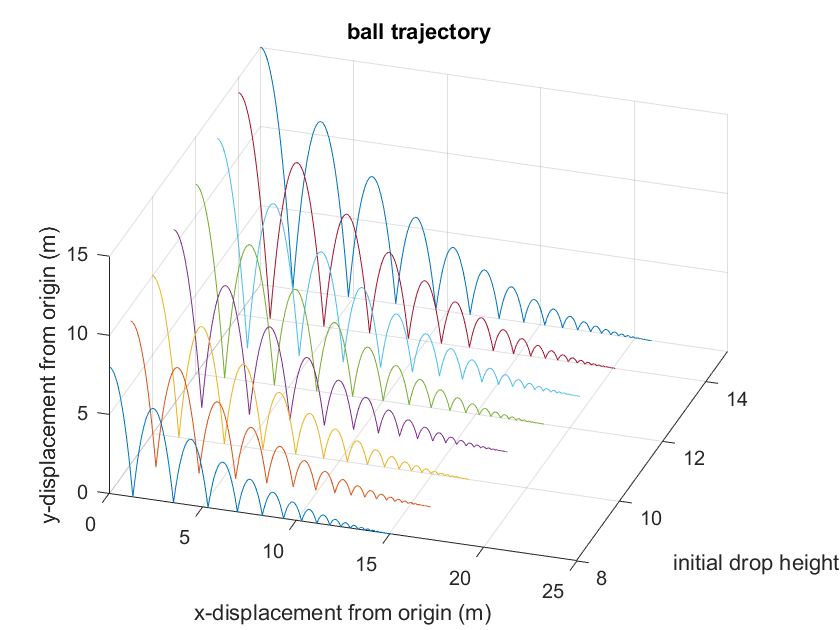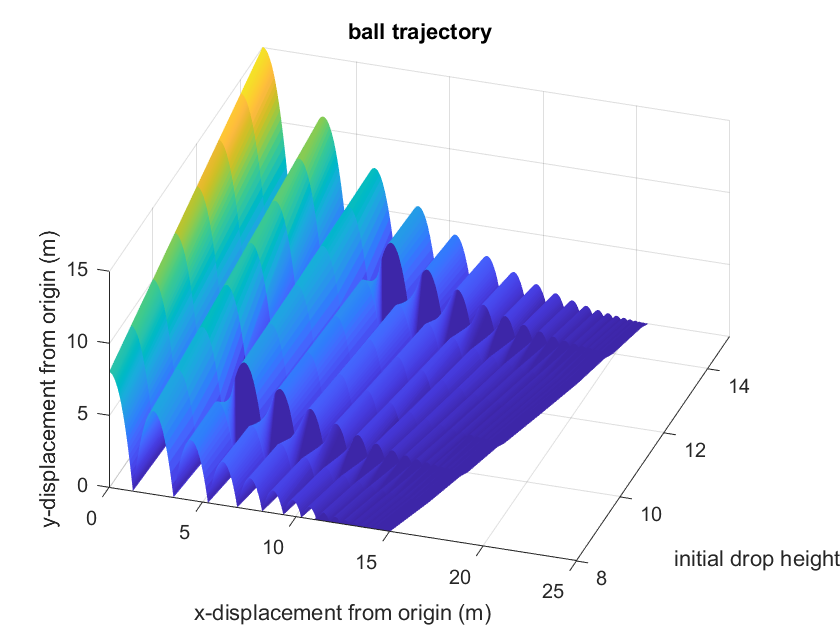

These two graphs are the same thing.

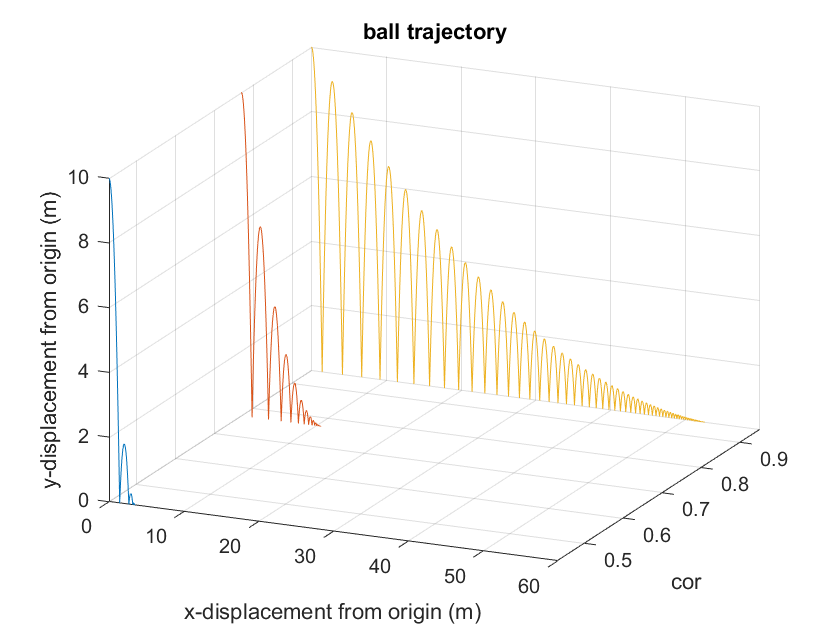

although it is not still here, we can imagine the results, can you please start talking about it? thanks

Talk about validating by interpreting trends?

## **Interpretation:**

## **Works Cited:**

Team 3_07 Miro Board: [https://miro.com/app/board/o9J_leaToAE=/](https://miro.com/app/board/o9J_leaToAE=/)

Newton's Physics Equations: [https://www.physicsclassroom.com/calcpad/newtlaws](https://www.physicsclassroom.com/calcpad/newtlaws)